function NewLayerTable=getMagnetizationEdgeFromLayerTable(LayerTable,app)
Model=app.GetCurrentModel;

%% 내전형

if any(contains(LayerTable.Properties.VariableNames,'Vertex'))

for LayerIndex=1:height(LayerTable)
    clear oneLayer
    clear MagnetTable
    oneLayer=LayerTable(LayerIndex,:);
    MagnetTable=LayerTable.MagnetTable(LayerIndex);

    for MagnetIndex=1:height(LayerTable.MagnetTable(LayerIndex,:))
        if iscell(MagnetTable) && length(MagnetTable)==1
        MagnetTable=MagnetTable{:};
        end
        clear EdgeIdTable
        EdgeIdTable=MagnetTable.Edge{MagnetIndex};
        for EdgeIdIndex=1:height(MagnetTable.Edge{MagnetIndex,:})
            EdgeId=EdgeIdTable.EdgeIds(EdgeIdIndex);
            EdgeIdTable.MagnetMagnetizeEdge(EdgeIdIndex)=0;
            StartPositionObj=Model.GetEdgeStartPosition(EdgeId);
            EndPositionObj=Model.GetEdgeEndPosition(EdgeId);    % %   cf - geomApp  EndVertexobj=CurItem.GetEndVertex;
            
            % StartPosition=getPositionStructFromPostionObj(StartPositionObj);
            StartPosition=getPositionStructFromDesignerPostionObj(StartPositionObj);
            EndPosition=getPositionStructFromDesignerPostionObj(EndPositionObj);
            % CenterBarrier
            CenterBarrierpoint1=oneLayer.PointOuter;
            CenterBarrierpoint2=oneLayer.PointInner;
            StartPositionVertexangle = calculateAngleBetweenThreePoints(CenterBarrierpoint1, CenterBarrierpoint2, StartPosition);
            EndPositionVertexangle = calculateAngleBetweenThreePoints(CenterBarrierpoint1, CenterBarrierpoint2, EndPosition);    
            tolerance = 1e-5; % 허용 가능한 오차 범위 설정 (원하는 값으로 조정)
             isSimilar = abs(StartPositionVertexangle-EndPositionVertexangle) < tolerance;
           if  isSimilar
               EdgeIdTable.MagnetMagnetizeEdge(EdgeIdIndex)=1;
            % else
            %     EdgeIdTable.MagnetMagnetizeEdge(EdgeIdIndex)=0;
           end
        end
        MagnetTable.Edge{MagnetIndex}=EdgeIdTable;
        % MagnetTable.Edge{MagnetIndex}=EdgeIdTable;
        LayerTable.MagnetTable{LayerIndex}=MagnetTable;
    end
end



NewLayerTable=LayerTable;
% 외전형 

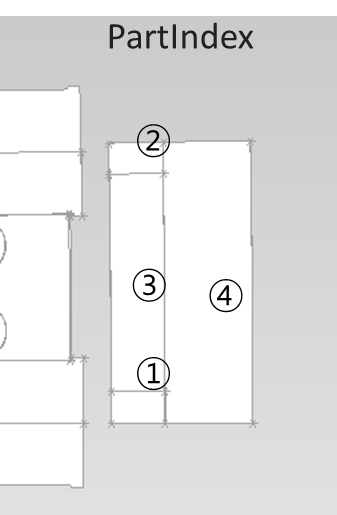

알고리즘 Edge의 두점과  midPosition의 R이 같은걸 Edge로 잡는다

else
    disp("AirBarrier가 없는 SPMSM 타입같네요")

    LayerIndex=1;
for MagnetIndex=1:height(LayerTable.MagnetTable(LayerIndex,:))
        clear EdgeIdTable
        MagnetTable=LayerTable.MagnetTable(LayerIndex,:);
        if iscell(MagnetTable) && length(MagnetTable)==1
        MagnetTable=MagnetTable{:};
        end
        EdgeIdTable=MagnetTable.Edge{:};
        MagnetizationEdgeIndex=getMagnetizationEdgeFromMagnetTableEdge(LayerTable.MagnetTable);
        EdgeIdTable.MagnetMagnetizeEdge(MagnetizationEdgeIndex)=1;
        MagnetTable.Edge{MagnetIndex}=EdgeIdTable;
        LayerTable.MagnetTable(LayerIndex,:)=MagnetTable;
end
NewLayerTable=LayerTable;

end